# Training Testing Split

clear;clc
rng(42) % For reproducibility

Data set splitting (80%-20% splitting)

% Loading ionosphere dataset
load ionosphere
tbl = array2table(X);
tbl.Y = Y;

% Number of the samples
n = length(tbl.Y);
% Generating cvpartition object hpartition
% 'Holdout' 0.2 means holding out 20% of the samples
hpartition = cvpartition(n,'Holdout',0.2);
% Forming training and testing sets with hpartition
idxTrain = training(hpartition);
tblTrain = tbl(idxTrain,:) % training sets

tblTrain = 281×35 table
    X1    X2      X3          X4          X5          X6          X7          X8         X9         X10         X11        X12         X13         X14         X15         X16         X17         X18         X19         X20         X21         X22         X23         X24         X25         X26         X27         X28         X29         X30         X31         X32         X33         X34        

idxTest = test(hpartition);
tblTest = tbl(idxTest,:) % testing sets

tblTest = 70×35 table
    X1    X2       X3          X4         X5          X6          X7          X8         X9         X10         X11         X12         X13        X14         X15         X16         X17         X18         X19        X20         X21         X22         X23         X24         X25         X26         X27        X28         X29        X30         X31         X32         X33         X34         

Stratified dataset splitting (80%-20% splitting)

% Generating labels
y = [ones(200,1); 2*ones(20,1)]; % the first 100 belongs to class "1", the last 10, class "2"

% If using unstratified data splitting
CV0 = cvpartition(y,'Holdout',0.2,'Stratify',false);
trainIdx0 = gather(CV0.training); % Use CV0.test to get split testing set
accumarray(y(trainIdx0),1)

ans =    159
    17


% If using stratified data splitting
CV0 = cvpartition(y,'Holdout',0.2,'Stratify',true);
trainIdx0 = gather(CV0.training); % Use CV0.test to get split testing set
accumarray(y(trainIdx0),1)

ans =    160
    16


Comment: number of samples strictly satisfying the original ratio and requested 20%.

K-fold CV

% Generating labels
y = [ones(200,1); 2*ones(20,1)]; % the first 100 belongs to class "1", the last 10, class "2"

% Using K-fold CV (stratified)
CV1 = cvpartition(y,'KFold', 4,'Stratify',true)

CV1 = K-fold cross validation partition
   NumObservations: 220
       NumTestSets: 4
         TrainSize: 165  165  165  165
          TestSize: 55  55  55  55

% Visualize the k-fold results
classes = categorical(y);
C = categories(classes)

C = 2×1 cell array
    {'1'}
    {'2'}


numClasses = size(C,1);
n = countcats(classes) % Number of observations in each class

n =    200
    20


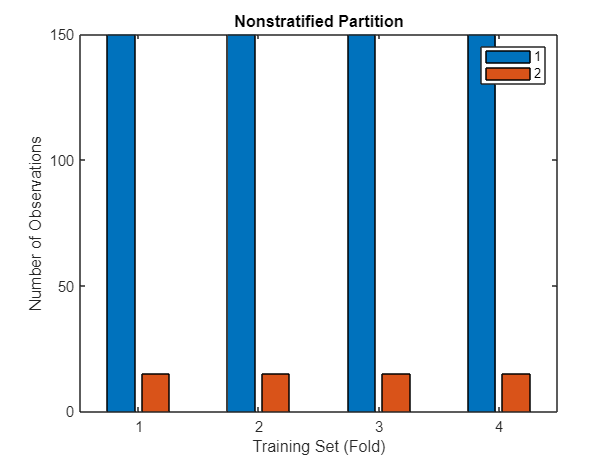

numFolds = CV1.NumTestSets;
nTrainingData = zeros(numFolds,numClasses);
for i = 1:numFolds
    trainingClasses = classes(CV1.training(i)); % Use CV1.test to get split testing set
    nCounts = countcats(trainingClasses); % Number of test set observations in each class
    nTrainingData(i,:) = nCounts';
end

bar(nTrainingData)
xlabel('Training Set (Fold)')
ylabel('Number of Observations')
title('Nonstratified Partition')
legend(C)

Leave-one-out CV

% Generating dataset
X = [1 2 3 4 5 6 7 8 9 20]';
% Configuring leave-one-out CV
c = cvpartition(10,'Leaveout')

c = Leave-one-out cross validation partition
   NumObservations: 10
       NumTestSets: 10
         TrainSize: 9  9  9  9  9  9  9  9  9  9
          TestSize: 1  1  1  1  1  1  1  1  1  1

% The first training - excluding the last sample to form testing set
c.training(1)

ans = 10×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0


% The second training - excluding the 9-th sample to form testing set
c.training(2)

ans = 10×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   0
   1
